# UR5 Trajectory Simulation

This example shows how to generate and simulate interpolated joint trajectories to move from an initial to a desired end-effector pose. The timing of the trajectories is based on an approximate desired end of arm tool (EOAT) speed. This is based off of a modified example made by Mathworks:

https://www.mathworks.com/help/robotics/ug/plan-and-execute-trajectory-kinova-gen3.html

## Creating the Robot

Load the Universal Robots UR5 rigid body tree (RBT) robot model.

robot = loadrobot('universalUR5','DataFormat','row','Gravity',[0 0 -9.81]);
endEffector = "tool0";

## Inverse Kinematics

Set current robot joint configuration.

% Compute initial robot joint configuration using inverse kinematics and
% set it as the robot's current configuration

% The initial task coordinates need to be expressed as a homogenous
% transformation matrix. We can do this by converting and combining a
% transformation vector for the end effector's position, and an euler angle
% representation for its orientation.

taskInit = trvec2tform([[0 0 0.35]])*eul2tform([0 pi/2 0]);

% MATLAB's built-in inverse kinematics solver uses an inverseKinematics
% object that considers the particular structure of the robot being
% analyzed.

ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

% In order to calculate the inverse kinematics for a particular end
% effector pose, we need to provide the ik object with a 'weights'
% parameter telling it how much we care about the accuracy for each
% of the pose's components. Since MATLAB is performing a numerical
% calculation, we also need to provide it with an initial guess for the
% robot's configuration. We set this initial guess as the robot's
% homeConfiguration with robot.homeConfiguration.

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);
currentRobotJConfig = wrapToPi(currentRobotJConfig);

**Question:** *Using the above code for the inverse kinematics, can you find the joint coordinates needed to position the end effector at a position of [0 0.3 0.1] with a ZYX Euler representation of [pi/2 0 0]?*

Get number of joints.

numJoints = numel(currentRobotJConfig);

Specify the trajectory time step and approximate desired tool speed.

timeStep = 0.1; % seconds

Set the initial and final end-effector pose.

jointInit = currentRobotJConfig;
taskInit = getTransform(robot,jointInit,endEffector);
% Set the desired end-effector pose in the same way as we defined the
% initial pose
taskFinal = trvec2tform([0.4,0,0.6])*eul2tform([pi/2 0 0]);

Define some trajectory parameters:

distance = norm(tform2trvec(taskInit)-tform2trvec(taskFinal));

initTime = 0;
finalTime = 10;
trajTimes = initTime:timeStep:finalTime;
timeInterval = [trajTimes(1); trajTimes(end)];

## Generate Joint-Space Trajectory

Calculate the initial and desired joint configurations using inverse kinematics. 

initialGuess = wrapToPi(jointInit);
jointFinal = ik(endEffector,taskFinal,weights,initialGuess);
jointFinal = wrapToPi(jointFinal);

## Control Joint-Space Trajectory

In order for the robot to follow a trajectory, we need to implement a controller for our model. While most of details of this are currently beyond the scope of this lab, be aware that the robot arm controlling each of its joints individually in order to travel from its initial configuration, to its final desired state. Here are some external references of the controller we've implemented, courtesy of Mathworks:

[https://www.mathworks.com/help/robotics/ref/jointspacemotionmodel.html](https://www.mathworks.com/help/robotics/ref/jointspacemotionmodel.html)

[https://www.mathworks.com/help/robotics/ug/simulate-joint-space-trajectory-tracking.html](https://www.mathworks.com/help/robotics/ug/simulate-joint-space-trajectory-tracking.html) 

Create a joint space motion model for PD control on the joints. The `jointSpaceMotionModel` object models the motion of a rigid body tree model and uses proportional-derivative control on the specified joint positions.

jsMotionModel = jointSpaceMotionModel('RigidBodyTree',robot,'MotionType','PDControl');
jsMotionModel.Kp = diag(10*ones(1,6));
jsMotionModel.Kd = diag(10*ones(1,6));

Set initial states (joint positions and velocities), and the final joint velocity: 

q0 = jointInit; 
qd0 = zeros(size(q0));
qdf = zeros(size(q0));

Use `ode15s` to simulate the robot motion. Again, an example helper function is used as the function handle input to the ODE solver in order to update the reference inputs at each instant in time. The joint-space states are output in `stateJoint`.

[tJoint,stateJoint]=ode15s(@(t,y)derivative(jsMotionModel,y,[jointFinal,qdf]),trajTimes,[q0,qd0]);

## Visualize Robot Trajectories

Show the initial configuration of the robot.

show(robot,currentRobotJConfig,'PreservePlot',false,'Frames','off');
hold on
axis([-1 1 -1 1 -0.1 1.5]);

Visualize the joint-space trajectory. Iterate through the `jointTask` states and interpolate based on the current time.

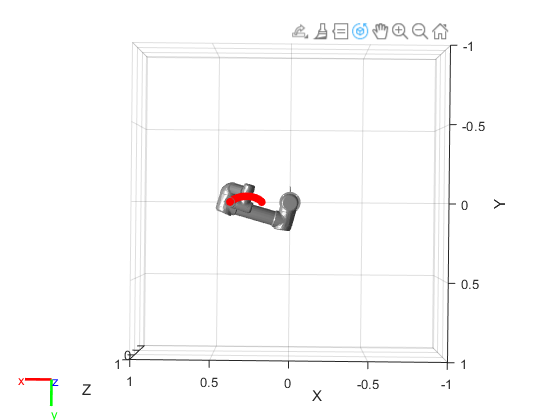


for i=1:length(trajTimes)
    % Current time 
    tNow= trajTimes(i);
    % Interpolate simulated joint positions to get configuration at current time
    configNow = interp1(tJoint,stateJoint(:,1:numJoints),tNow);
    poseNow = getTransform(robot,configNow,endEffector);
    show(robot,configNow,'PreservePlot',false,'Frames','off');
    plot3(poseNow(1,4),poseNow(2,4),poseNow(3,4),'r.','MarkerSize',20)
    drawnow;
end

**Question: ***Why is the path of the robot not a straight line? Investigate this by plotting the joint coordinates over time in their own plots below. You can do this by completing the commented out plot() commands.  The joint positions for the joint-controlled trajectory are stored in stateJoint(:,1:numJoints) and their velocities are stored in stateJoint(:,numJoints+1:end). If you want to learn more about what is going on, you can read further details here - although the specifics on the controllers are beyond the material currently covered in this class:*

https://blogs.mathworks.com/racing-lounge/2019/11/06/robot-manipulator-trajectory/

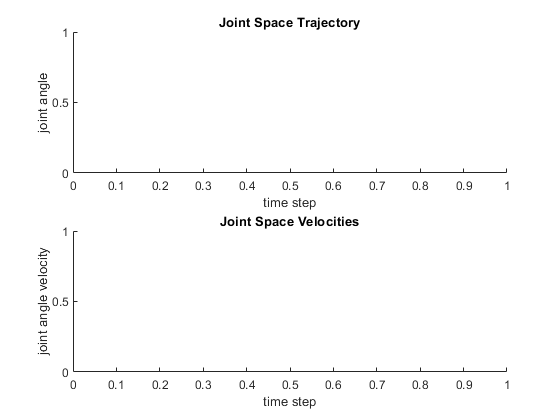

figure()
subplot(2,1,1)
%plot()
title('Joint Space Trajectory')
xlabel('time step')
ylabel('joint angle')
subplot(2,1,2)
%plot()
title('Joint Space Velocities')
xlabel('time step')
ylabel('joint angle velocity')

*Version 1: Cormac O'Neill, 2021*